# Uniform sampling of E. coli core

## Author(s): German A. Preciat Gonzalez

## INTRODUCTION

The flux space $\Omega$ for a given set of biochemical and physiologic constraints is represented by: 


$$\Omega = \{v \mid Sv=b; l \leq v\leq u\}$$


where $v$ represents feasible flux vectors,  $S\in\mathcal{Z}^{m\times n}$ the stoichiometric matrix, while $l$ and $u$ are lower and upper bounds on fluxes. These criteria still allow a wide range of admissible flux distributions which, in FBA are commonly further restricted by introducing an objective to optimise, transforming the question of admissible fluxes into an FBA problem${\;}^1$ of the form


$$\begin{array}{ll}
\min\limits _{v} & c^{T}v\\
\text{s.t.} & Sv=b,\\
 & l\leq v\leq u,
\end{array}$$


where $c$ is a linear biological objective function (biomass, ATP consumption, HEME production, etc.). Even under these conditions there is commonly a range of optimal flux distributions, which can be investigated using flux variability analysis. If the general capabilities of the model are of interest, however, uniform sampling of the entire flux space $\Omega$ is able to provide an unbiased characterization, and therefore, can be used to investigate the biochemical networks. It requires collecting a statistically meaningful number of flux distributions uniformly spread throughout the whole flux space and then analysing their properties. There are three basic steps to perform a uniform sampling for a set of feasible fluxes:

- Define the flux space to be sampled from physical and biochemical constraints

- Randomly sample the defined flux space based on uniform statistical criteria

- If is necessary, section the flux space according to post-sampling.

In COBRA v3 the default sampling algorithm is coordinate hit-and-run with rounding (CHRR). This algorithm first rounds the anisotropic flux space  Ω using a maximum volume ellipsoid algorithm${\;}^3$ and then performs a uniform sampling based on the provably efficient hit-and-run random walk${\;}^4$. Below is a high-level illustration of the process to uniformly sample a random metabolic flux vector $v$ from the set $\Omega$ of all feasible metabolic fluxes (grey). **1)** Apply a rounding transformation $T$ to $\Omega$. The transformed set $\Omega \prime =T\Omega \;$ is such that its maximal inscribed ellipsoid (blue) approximates a unit ball. **2)** Take $q$ steps of coordinate hit-and-run. At each step, i) pick a random coordinate direction $e_i$, and ii) move from current point $v\prime_k \in \Omega \prime$ to a random point $v\prime_{k+1} \in \Omega \prime$ along $v\prime_k +\alpha e_i \cap \Omega \prime$. **3)** Map samples back to the original space by applying the inverse transformation, i.e., $v_k =T^{-1} v\prime_k$.

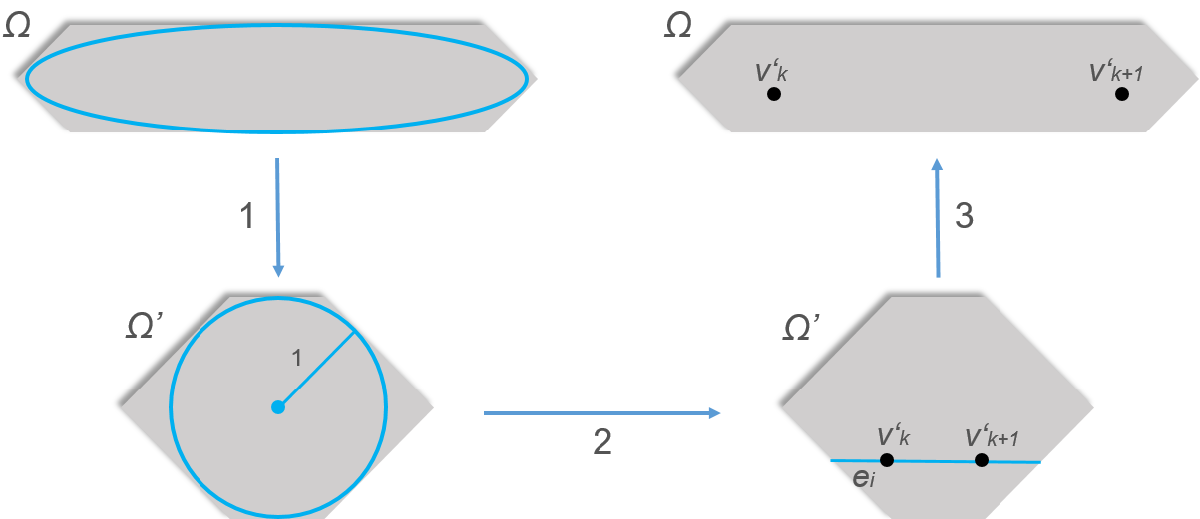

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

Please note that some of the plotting options in the tutorial require Matlab 2016a or higher. Moreover, the tutorial requires a working installation of the Parallel Computing Toolbox.

In this tutorial, we will perform FVA using the function `fluxVariability`. Change the variable `options.useFastFVA = 1` to use `fastFVA `instead`.` Note that the solver ibm_cplex is required for the function fastFVA.

options.useFastFVA = 0;

## PROCEDURE

## Load E. coli core model

The most appropriate way to load a model into The COBRA Toolbox is to use the `readCbModel` function. 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
    modelOri = readCbModel(fileName);
end

Each model.subSystems{x} is a character array, and this format is retained.


%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;

## E. coli core in aerobic an anaerobic conditions

Remove the objective from the model and set a small lower bound on the rate of the biomass reaction

biomassRxnAbbr = 'Biomass_Ecoli_core_N(w/GAM)-Nmet2';
ibm = find(ismember(model.rxns, biomassRxnAbbr));  % column index of the biomass reaction
model.lb(ibm)=0.05;
model.c(:)=0;


We will investigate ATP energy production with limited and unlimited oxygen uptake. 

aerobicModel = changeRxnBounds(model,'EX_o2(e)',-17,'l');
anAerobicModel = changeRxnBounds(model,'EX_o2(e)',-1,'l');

## Flux variability analysis

Flux variability analysis (FVA) returns the minimum and maximum possible flux through every reaction in a model.

if options.useFastFVA
    [minUn, maxUn] = fastFVA(aerobicModel, 100);
    [minLim, maxLim] = fastFVA(anAerobicModel, 100);
else
    [minUn, maxUn] = fluxVariability(aerobicModel);
    [minLim, maxLim] = fluxVariability(anAerobicModel);
end

fprintf('Max. biomass production with oxygen uptake: %.4f/h.\n', maxUn(ibm));

Max. biomass production with oxygen uptake: 0.7637/h.


fprintf('Max. biomass production without oxygen uptake: %.4f/h.\n\n', maxLim(ibm));

Max. biomass production without oxygen uptake: 0.2477/h.



An overall comparison of the FVA results can be obtained by computing the [Jaccard index](https://en.wikipedia.org/wiki/Jaccard_index) for each reaction. The Jaccard index is here defined as the ratio between the intersection and union of the flux ranges in the aerobic and anaerobic models. A Jaccard index of 0 indicates completely disjoint flux ranges and a Jaccard index of 1 indicates completely overlapping flux ranges. The mean Jaccard index gives an indication of the overall similarity between the models.

J = fvaJaccardIndex([minUn, minLim], [maxUn, maxLim]);
fprintf('Mean Jaccard index = %.4f.\n', mean(J));

Mean Jaccard index = 0.5524.


To visualise the FVA results, we plot the flux ranges as errorbars, with reactions sorted by the Jaccard index.

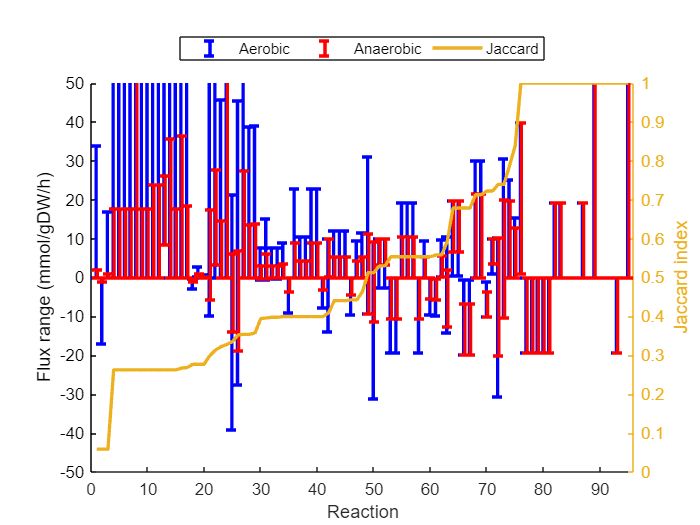

E = [(maxUn - minUn)/2 (maxLim - minLim)/2];
Y = [minUn minLim] + E;
X = [(1:length(Y)) - 0.1; (1:length(Y)) + 0.1]';

[~, xj] = sort(J);

f1 = figure;
if strcmp(version('-release'), '2016b')
    errorbar(X, Y(xj, :), E(xj, :), 'linestyle', 'none', 'linewidth', 2, 'capsize', 0);
else
    %errorbar(X, Y(xj, :), E(xj, :), 'linestyle', 'none', 'linewidth', 2);
    hold on
    errorbar(X(:,1), Y(xj, 1), E(xj, 1), 'linestyle', 'none', 'linewidth', 2,'Color','b');
    errorbar(X(:,2), Y(xj, 2), E(xj, 2), 'linestyle', 'none', 'linewidth', 2,'Color','r');
end
set(gca, 'xlim', [0, length(Y) + 1])

xlabel('Reaction')
ylabel('Flux range (mmol/gDW/h)')
ylim([-50,50])
yyaxis right
plot(J(xj),'linewidth', 2)
legend('Aerobic', 'Anaerobic', 'Jaccard','location', 'northoutside', ...
    'orientation', 'horizontal')
ylabel('Jaccard index')

## Undersampling

CHRR can be called via the function `sampleCbModel`. The main inputs to `sampleCbModel` are a COBRA model structure, the name of the selected sampler and a parameter struct that controls properties of the sampler used. In the instance of CHRR, two parameters are important: the sampling density (`nStepsPerPoint)` and the number of samples (`nPointsReturned). `The total length of the random walk is `nStepsPerPoint*nPointsReturned`. The time it takes to run the sampler depends on the total length of the random walk and the size of the model${\;}^2$. However, using sampling parameters that are too small will lead to invalid sampling distributions, e.g.,

options.nStepsPerPoint = 1;
options.nPointsReturned = 500;

An additional on/off parameter (`toRound`) controls whether or not the polytope is rounded. Rounding large models can be slow but is strongly recommended for the first round of sampling. Below we show how to get around this step in subsequent rounds. 

options.toRound = 1;

The method outputs two results. First, the model used for sampling (in case of `toRound = 1` this would be the rounded model), and second, the samples generated. 

To sample the aerobic and anaerobic E. coli core models use:

[P_un, X1_un] =  sampleCbModel(aerobicModel, [], [], options);

Checking for width 0 facets...
Currently (P.A, P.b) are in 95 dimensions
Checking for width 0 facets...
Found 8 degenerate reactions, adding them to the equality subspace.


Now in 24 dimensions after restricting
Removed 174 zero rows
Preconditioning A with gmscale
Rounding...
Iteration 1: reg=1.0e-04, ellipsoid vol=1.1e+50, longest axis=3.6e+02, shortest axis=3.2e+01, x0 dist to bdry=5.7e+01, time=4.2e-01 seconds
Iteration 2: reg=1.0e-05, ellipsoid vol=1.5e+01, longest axis=2.9e+00, shortest axis=8.3e-01, x0 dist to bdry=1.0e+00, time=1.5e-01 seconds
Iteration 3: reg=1.0e-06, ellipsoid vol=1.3e+01, longest axis=1.5e+00, shortest axis=1.1e+00, x0 dist to bdry=1.1e+00, time=8.6e-02 seconds
  Converged!
Iteration 4: reg=1.0e-07, ellipsoid vol=1.0e+00, longest axis=1.0e+00, shortest axis=1.0e+00, x0 dist to bdry=1.0e+00, time=5.1e-01 seconds
Maximum volume ellipsoid found, and the origin is inside the transformed polytope.
Generating samples...


[P_lim, X1_lim] = sampleCbModel(anAerobicModel, [], [], options);

Checking for width 0 facets...
Currently (P.A, P.b) are in 95 dimensions
Checking for width 0 facets...
Found 8 degenerate reactions, adding them to the equality subspace.


Now in 24 dimensions after restricting
Removed 174 zero rows
Preconditioning A with gmscale
Rounding...
Iteration 1: reg=1.0e-04, ellipsoid vol=9.2e+38, longest axis=1.4e+02, shortest axis=1.1e+01, x0 dist to bdry=2.3e+01, time=1.3e-01 seconds
Iteration 2: reg=1.0e-05, ellipsoid vol=5.8e+00, longest axis=3.3e+00, shortest axis=8.9e-01, x0 dist to bdry=1.0e+00, time=3.4e-02 seconds
Iteration 3: reg=1.0e-06, ellipsoid vol=1.1e+01, longest axis=1.6e+00, shortest axis=1.1e+00, x0 dist to bdry=1.1e+00, time=4.6e-02 seconds
  Converged!
Iteration 4: reg=1.0e-07, ellipsoid vol=1.0e+00, longest axis=1.0e+00, shortest axis=1.0e+00, x0 dist to bdry=1.0e+00, time=2.2e-01 seconds
Maximum volume ellipsoid found, and the origin is inside the transformed polytope.
Generating samples...


The sampler outputs the sampled flux distributions (X_un and X_lim) and the rounded polytope (P_un and P_lim). Histograms of sampled ATP synthase show that the models are severely undersampled, as evidenced by the presence of multiple sharp peaks.

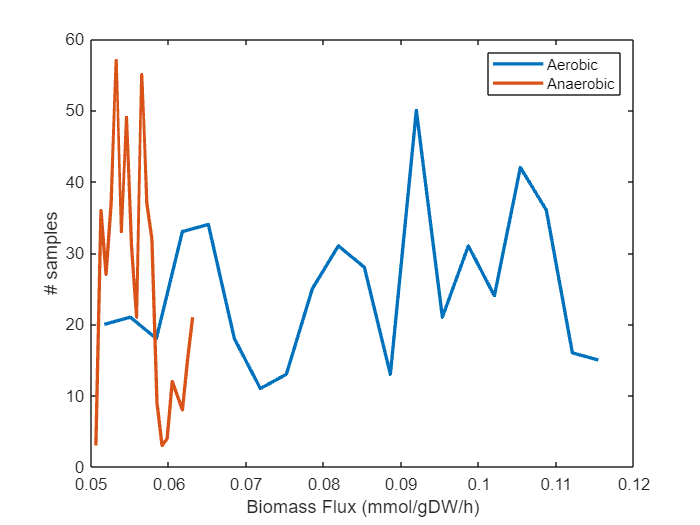

nbins = 20;
[yUn, xUn] = hist(X1_un(ibm, :), nbins,'linewidth', 2);
[yLims, xLims] = hist(X1_lim(ibm, :), nbins,'linewidth', 2);

f2 = figure;
plot(xUn, yUn, xLims, yLims,'linewidth', 2);
legend('Aerobic', 'Anaerobic')
xlabel('Biomass Flux (mmol/gDW/h)')
ylabel('# samples')

**Figure 1. **Undersampling results from selecting too small sampling parameters. 

## Sampling

The appropriate parameter values depend on the dimension of the polytope Ω defined by the model constraints (see intro). One rule of thumb says to set  $\textrm{nSkip}=8*{\dim \left(\Omega \right)}^2$ to ensure the statistical independence of samples. The random walk should be long enough to ensure convergence to a stationary sampling distribution${\;}^2$.

options.nStepsPerPoint = 8 * size(P_lim.A, 2);
options.nPointsReturned = size(P_lim.A, 2)^2;

This time, we can avoid the rounding step by inputting the rounded polytope from the previous round of sampling.

options.toRound = 0;
[~, X2_un] = sampleCbModel(aerobicModel, [], [], options, P_un);

Generating samples...


[~, X2_lim] = sampleCbModel(anAerobicModel, [], [], options, P_lim);

Generating samples...


The converged sampling distributions for the biomass reaction are much smoother, with a single peak near the minimum biomass flux.

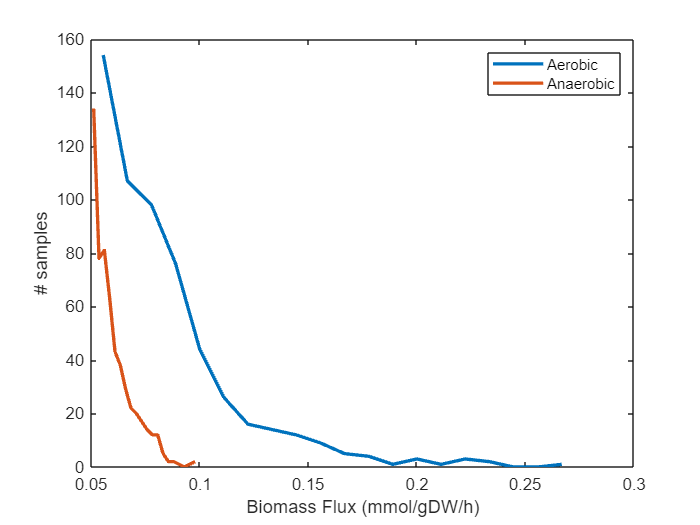

nbins = 20;
[yUn, xUn] = hist(X2_un(ibm, :), nbins,'linewidth', 2);
[yLims, xLims] = hist(X2_lim(ibm, :), nbins,'linewidth', 2);

f3 = figure;
p1 = plot(xUn, yUn, xLims, yLims,'linewidth', 2);
legend('Aerobic', 'Anaerobic')
xlabel('Biomass Flux (mmol/gDW/h)')
ylabel('# samples')

Adding the FVA results to the plot shows that the sampling distributions give more detailed information about the differences between the two models. In particular, we see that the biomass flux minima and maxima are not equally probable. The number of samples from both the aerobic and anaerobic models peaks at the minimum flux of zero, and decreases approximately monotonically towards the maximum growth rate. It decreases more slowly in the unanaerobic model, indicating that higher ATP production is more probable under unlimited oxygen uptake conditions. It is interesting to see that maximum ATP production is highly improbable in both models.

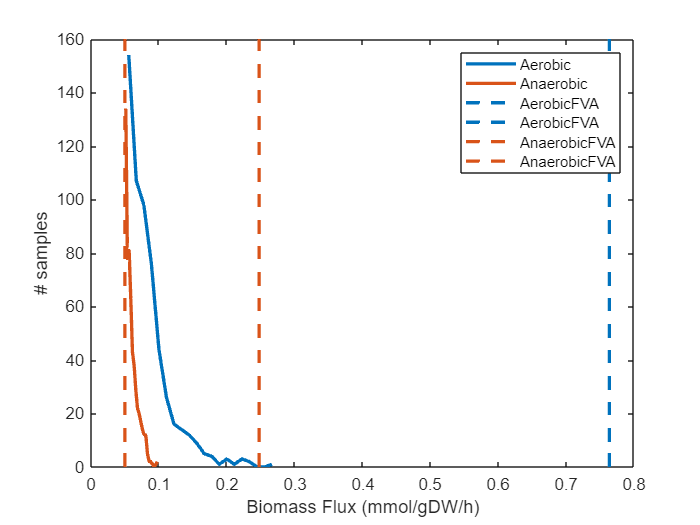

ylims = get(gca, 'ylim');
cUn = get(p1(1), 'color');
cLim = get(p1(2), 'color');

hold on
p2 = plot([minUn(ibm), minUn(ibm)], ylims, '--', [maxUn(ibm), maxUn(ibm)], ylims, '--','linewidth', 2);
set(p2,'color', cUn)
p3 = plot([minLim(ibm), minLim(ibm)], ylims, '--', [maxLim(ibm), maxLim(ibm)], ylims, '--','linewidth', 2);
set(p3, 'color', cLim)
legend('Aerobic', 'Anaerobic', 'AerobicFVA','AerobicFVA', 'AnaerobicFVA','AnaerobicFVA')
hold off

## Uncertanty reduction

To identify the most crucial reactions within a genome-scale model, one can leverage precomputed sampling data. This process involves three key steps included in the `identifySignificantRxns` function:

- **Sampling the Flux Space:** Initiate the analysis by sampling the flux space.

- **Calculating the Covariance Matrix:** Compute the covariance matrix based on the sampled data.

- **Computing the Euclidean Norm:** Determine the Euclidean norm to quantify the significance of reactions. 

These steps facilitate the identification of reactions for which constraining their bounds would have a substantial impact on the original flux space.

This approach was initially proposed in the work of *Preciat et al.*${\;}^5$ to determine which reactions should be measured exometabolically for maximizing the obtained information.

For the `aerobicModel` let's calculate the most significant exchange reactions.

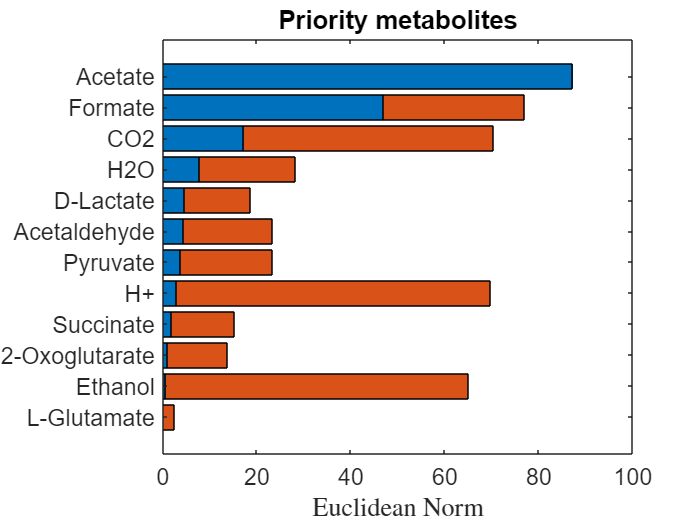

rankedNorms = identifySignificantRxns(aerobicModel, X2_un, [], true);

Acetate has been identified as the most significant reaction. Now, let's reduce acetate production in the model by half to observe its impact on the flux space.

aerobicModel2 = changeRxnBounds(aerobicModel, 'EX_ac(e)', aerobicModel.ub(findRxnIDs(aerobicModel, 'EX_ac(e)')) / 2,'u');
options.nStepsPerPoint = 1;
options.nPointsReturned = 100;
options.toRound = 1;
[P, ~] =  sampleCbModel(aerobicModel2, [], [], options);

Checking for width 0 facets...
Currently (P.A, P.b) are in 95 dimensions
Checking for width 0 facets...
Found 8 degenerate reactions, adding them to the equality subspace.


Now in 24 dimensions after restricting
Removed 174 zero rows
Preconditioning A with gmscale
Rounding...
Iteration 1: reg=1.0e-04, ellipsoid vol=1.1e+50, longest axis=3.6e+02, shortest axis=3.2e+01, x0 dist to bdry=5.7e+01, time=3.9e-01 seconds
Iteration 2: reg=1.0e-05, ellipsoid vol=1.5e+01, longest axis=2.9e+00, shortest axis=8.3e-01, x0 dist to bdry=1.0e+00, time=1.0e+00 seconds
Iteration 3: reg=1.0e-06, ellipsoid vol=1.3e+01, longest axis=1.5e+00, shortest axis=1.1e+00, x0 dist to bdry=1.1e+00, time=3.4e-01 seconds
  Converged!
Iteration 4: reg=1.0e-07, ellipsoid vol=1.0e+00, longest axis=1.0e+00, shortest axis=1.0e+00, x0 dist to bdry=1.0e+00, time=5.4e-01 seconds
Maximum volume ellipsoid found, and the origin is inside the transformed polytope.
Generating samples...


options.nStepsPerPoint = 8 * size(P.A, 2);
options.nPointsReturned = size(P.A, 2)^2;
options.toRound = 0;
[~, samples] =  sampleCbModel(aerobicModel2, [], [], options);

Checking for width 0 facets...
Currently (P.A, P.b) are in 95 dimensions
Checking for width 0 facets...
Found 8 degenerate reactions, adding them to the equality subspace.


Now in 24 dimensions after restricting
Removed 174 zero rows
Preconditioning A with gmscale
Rounding...
Generating samples...


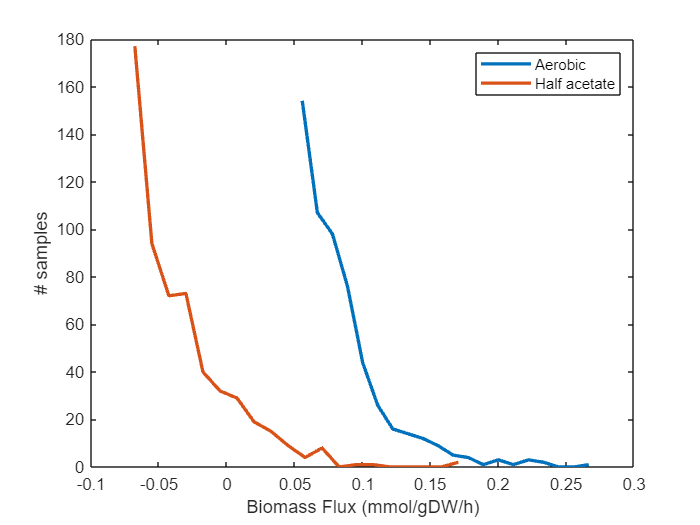

nbins = 20;
[yUn, xUn] = hist(X2_un(ibm, :), nbins,'linewidth', 2);
[yHalf, xHalf] = hist(samples(ibm, :), nbins,'linewidth', 2);

plot(xUn, yUn, xHalf, yHalf,'linewidth', 2);
legend('Aerobic', 'Half acetate')
xlabel('Biomass Flux (mmol/gDW/h)')
ylabel('# samples')

When modifying the oxygen exchange (`EX_o2(e)`) bounds from -1000 to 1000 to a more constrained range of -17 to 1000, an associated alteration is observed in the acetate exchange (`EX_ac(e)`) based on the identified significant reactions, shifting from the range of 0 to 1000 to a range of 0 to 500. Consequently, this adjustment impacts the distribution of fluxes related to half acetate production, influencing biomass production in a comparable manner.

## References

- Orth, J. D., Thiele I., and Palsson, B. Ø. What is flux balance analysis? *Nat. Biotechnol.* 28(3), 245-248 (2010).

- Haraldsdóttir, H. S., Cousins, B., Thiele, I., Fleming, R.M.T., and Vempala, S. CHRR: coordinate hit-and-run with rounding for uniform sampling of constraint-based metabolic models. *Bioinformatics*. 33(11), 1741-1743 (2016).

- Zhang, Y. and Gao, L. On Numerical Solution of the Maximum Volume Ellipsoid Problem. *SIAM J. Optimiz*. 14(1), 53-76 (2001).

- Berbee, H. C. P., Boender, C. G. E., Rinnooy Ran, A. H. G., Scheffer, C. L., Smith, R. L., Telgen, J. Hit-and-run algorithms for the identification of nonredundant linear inequalities. *Math. Programming*, 37(2), 184-207 (1987).

- Preciat G., Lucumi Moreno E., Wegrzyn A.B., Willacey C.C.W., Modamio J., Monteiro F.L., El Assal D., Schurink A., Oliveira M.A.P., Zhang Z., Cousins B., Haraldsdóttir H.S., Zach S., Vempala S., Hengerer B., Saunders M.A., Harms A., Schwamborn J.C., Thiele I., Hankemeier T., Fleming R.M.T.. Mechanistic model-driven exometabolomic characterisation of human dopaminergic neuronal metabolism